% clear; close all;

% Load data from MAT-file into workspace
blog = load("newdata/lab3_sim_lab2p01.eps")
DIR = "newdata/"
test_timeseries = load("angles10.mat")

test_timeseries = struct with fields:
    ans: [7×17501 double]


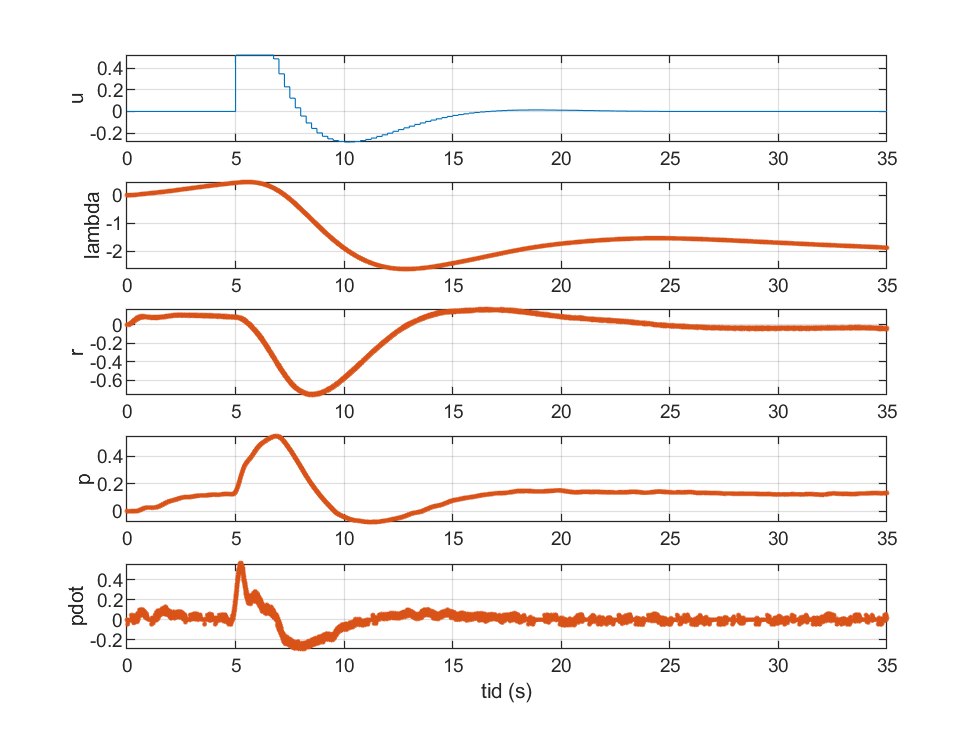

sim_data = test_timeseries.ans;

simTime = sim_data(1, :);
% uTime = uref.Data;
x1sim = sim_data(2, :); % lambda
x2sim = sim_data(3, :); % r
x3sim = sim_data(4, :); % p
x4sim = sim_data(5, :); % p_dot

% elevation = sim_data(6, :);
% elevation_rate = sim_data(7, :);

% % Setup gca 
% figure(); grid on; hold on
% % set(gca,'YAxisLocation','right')
% axis padded

% Plot data
% plot(time, travel,"linewidth", 1,"linestyle", ".");
% plot(time, pitch,"linewidth", 1,"linestyle", ".");

% Set title, labels and legends
% title("Testing loading data for plotting", "Interpreter", "latex", 'fontweight','bold', "FontSize", 14)
% legend(["Travel" "Elevation"], "Location", "best", "Interpreter", "latex")
% xlabel("Time $t$ (s)","Interpreter","latex")
% ylabel("Radians" , "Interpreter","latex")

figure(2)
subplot(511)
stairs(t,u),grid
ylabel('u')
subplot(512)
plot(simTime,x1sim,'m',simTime,x1sim, '.'),grid
ylabel('lambda')
subplot(513)
plot(simTime,x2sim,'m',simTime,x2sim', '.'),grid
ylabel('r')
subplot(514)
plot(simTime,x3sim,'m',simTime,x3sim, '.'),grid
ylabel('p')
subplot(515)
plot(simTime,x4sim,'m',simTime,x4sim','.'),grid
xlabel('tid (s)'),ylabel('pdot')


% saveas(gcf, "simP_10.eps", "-depsc")

Error using saveas (line 179)
Unsupported format or extension: -depsc


% subplot(8, 1, 1);
% hold on
% grid on
% plot(x_time, u_pitch_opt, "linewidth", 2, "linestyle","--");
% plot(u_time, u_pitch, "linewidth", 2);
% xlabel("Time $t$ (s)","Interpreter", "latex")
% ylabel("$rad$" , "Interpreter", "latex")
% legend('u*')
% hold off
% title("Input: Pitch")
% 
% subplot(8, 1, 2);
% hold on
% grid on
% plot(x_time, u_elevation_opt, "linewidth", 2,"linestyle","--");
% plot(x_time, u_elevation, "linewidth", 2);
% xlabel("Time $t$ (s)","Interpreter", "latex")
% ylabel("$rad$" , "Interpreter", "latex")
% legend('$p^{*}$', 'p', "Interpreter", "latex")
% hold off
% title("Input: Elevation")
% 
% subplot(8, 1, 3);
% hold on
% grid on
% plot(x_time, x_travel_opt, "linewidth", 2,"linestyle","--");
% plot(x_time, x_travel, "linewidth", 2);
% xlabel("Time $t$ (s)","Interpreter", "latex")
% ylabel("$rad$" , "Interpreter", "latex")
% legend('\lambda*', '\lambda') 
% hold off
% title("Travel")
% 
% subplot(8, 1, 4);
% hold on
% grid on
% plot(x_time, x_travel_rate_opt, "linewidth", 2,"linestyle","--");
% plot(x_time, x_travel_rate, "linewidth", 2);
% xlabel("Time $t$ (s)","Interpreter", "latex")
% ylabel("$rad$" , "Interpreter", "latex")
% legend('$\dot{\lambda^{*}}$', '$\dot{\lambda}$',"Interpreter", "latex")
% hold off
% title("Travel rate")
% 
% subplot(8, 1, 5);
% hold on
% grid on
% plot(x_time, x_pitch_opt, "linewidth", 2,"linestyle","--");
% plot(x_time, x_pitch, "linewidth", 2);
% xlabel("Time $t$ (s)","Interpreter", "latex")
% ylabel("$rad$" , "Interpreter", "latex")
% legend('$p*$', '$p$', "Interpreter", "latex") 
% hold off
% title("Pitch")
% 
% subplot(8, 1, 6);
% hold on
% grid on
% plot(x_time, x_pitch_rate_opt, "linewidth", 2,"linestyle","--");
% plot(x_time, x_pitch_rate, "linewidth", 2);
% xlabel("Time $t$ (s)","Interpreter", "latex")
% ylabel("$rad$" , "Interpreter", "latex")
% legend('$\dot{p*}$', '$\dot{p}$', "Interpreter", "latex") 
% hold off
% title("Pitch rate")
% 
% subplot(8, 1, 7);
% hold on
% grid on
% plot(x_time, x_elevation_opt, "linewidth", 2,"linestyle","--");
% plot(x_time, x_elevation, "linewidth", 2);
% xlabel("Time $t$ (s)","Interpreter", "latex")
% ylabel("$rad$" , "Interpreter", "latex")
% legend('$e*$', '$e$',"Interpreter", "latex")
% hold off
% title("Elevation")
% 
% subplot(8, 1, 8);
% hold on
% grid on
% plot(x_time, x_elevation_rate_opt, "linewidth", 2,"linestyle","--");
% plot(x_time, x_elevation_rate, "linewidth", 2);
% xlabel("Time $t$ (s)","Interpreter", "latex")
% ylabel("$rad$" , "Interpreter", "latex")
% legend('$\dot{e^{*}}$', '$\dot{e}$',"Interpreter", "latex")
% hold off
% title("Elevation rate")